N=50;
M=50;
K=1e2;
sigma=2;
x=linspace(0,M,M);
y=linspace(0,N,N);
a=2*M*rand(K,1);
b=2*N*rand(K,1);
xc=zeros(size(x));
yc=zeros(size(y));
for i=1:size(x)
    for j=1:size(a)
        if j==i
            xc(i)=j
        end
    end
end

xc =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



for i=1:size(y)
    for j=1:size(b)
        if j==i
            yc(i)=j
        end
    end
end

yc =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


%x,y=meshgrid(x,y);
xc,yc=meshgrid(xc,yc);

xc =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


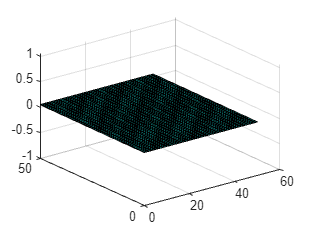

d=100;
z=(1/(8*sqrt(2*pi)))*exp(-((x-xc).^2-(y-yc).^2)./(2*sigma^2));
% z=zeros(size(z));

v = sin(x) + cos(y);
c = x.*y;
%x,y,z=meshgrid(x,y,z);
figure();
surf(x,y,z);